% Ensure that the constants required here are defined
if ~exist('QUAD_COPTER_MLX_RAN', 'var') || ~QUAD_COPTER_MLX_RAN
    disp('''quad_copter.mlx'' has not been run yet. Running now ...'); 
    error('No I''m not, as far as I can see there is no documented way of running a livescript from the command line !');
end

if ~exist('logsout', 'var')
    error('Simulink model has not been run yet.');
end

# Comparing the MATLAB and Simulnk models 

The Matlab and Simulink models don't line up for some reason. The task here is to find out why. 

## Figure 1: $\Theta° \Rightarrow \Theta$

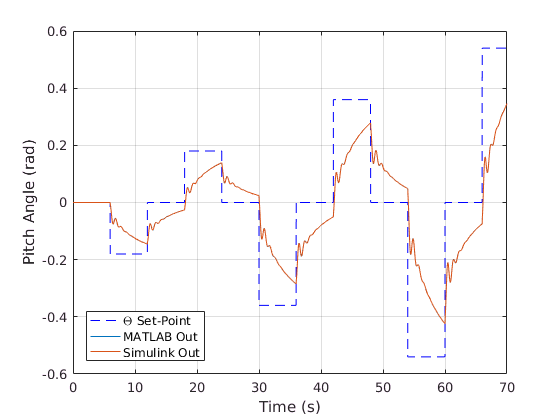

ml_theta_in  = test_input_ts;

sml_theta_in = logsout.getElement('Theta Set-Point');
sml_theta_out = logsout.getElement('Theta');

figure()
    plot(ml_theta_in.time, ml_theta_in.signals.values, 'b--', ...
         ml_theta_in.time, test_theta,                        ...
         sml_theta_in.Values.Time, sml_theta_out.Values.Data  ...
    );
    legend('\Theta Set-Point', 'MATLAB Out', 'Simulink Out', ...
        'location', 'southWest');
    xlabel('Time (s)'); ylabel('Pitch Angle (rad)');  

The systems are globally similar but show slight differences. Why ?

## Figure 2: $q° \Rightarrow q$

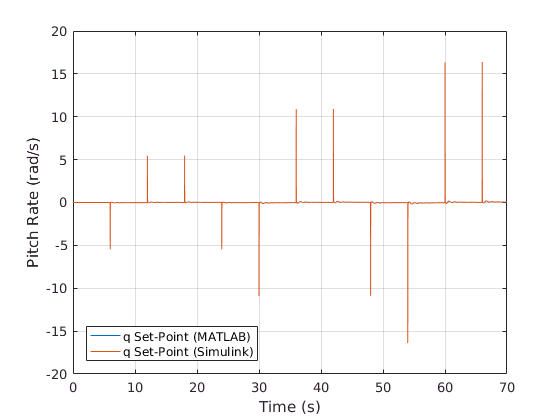

ml_q_in = test_q_set_point;
ml_q_out = test_output_q;

sml_q_in = logsout.getElement('q Set-Point');
sml_q_out = logsout.getElement('q');

figure()
    plot(ml_theta_in.time, ml_q_in, ...
        sml_q_in.Values.Time, sml_q_in.Values.Data);
    legend('q Set-Point (MATLAB)', 'q Set-Point (Simulink)', ...
        'location', 'southWest');
    xlabel('Time (s)'); ylabel('Pitch Rate (rad/s)');    

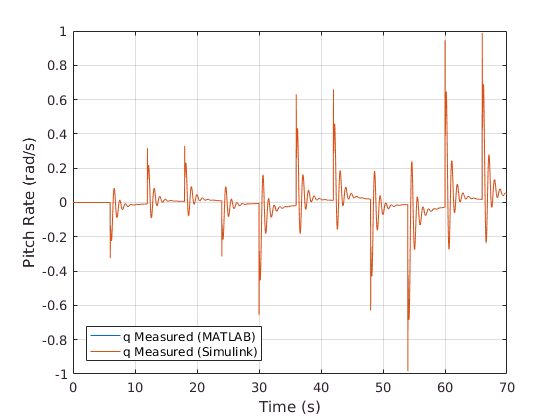

    
figure()
    plot(ml_theta_in.time, ml_q_out, ...
        sml_q_out.Values.Time, sml_q_out.Values.Data);
    legend('q Measured (MATLAB)', 'q Measured (Simulink)', ...
        'location', 'southWest');
    xlabel('Time (s)'); ylabel('Pitch Rate (rad/s)');    